data = readmatrix('./s21_results/s21_data_1.csv');

fstart = 1e9;
fend = 6e9;
bw = fend - fstart;
c = physconst('LightSpeed');
v = c;
dr = v / (2 * bw);

df = 1e7;
f = fstart:df:fend;

amplitude = data(:, 2);
phase = data(:, 3);

s = amplitude .* exp (1i * phase);

st = ifft(s);

st = st';

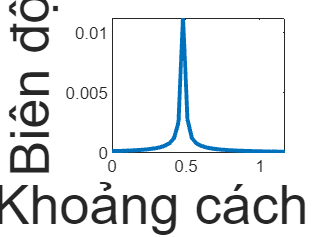

figure
plot((0:39)*dr, abs(st(1:40)), 'LineWidth', 2)
gca.XAxis.FontSize = 27;
gca.YAxis.FontSize = 27;
xlabel('Khoảng cách (m)', 'FontSize', 27);
ylabel('Biên độ', 'FontSize', 27);

[sorted_value, sorted_index] = sort(abs(st(1:60)), 'descend');

distance1 = sorted_index(1) * dr

distance1 = 0.5096

distance2 = sorted_index(2) * dr

distance2 = 0.5396